clear all, close all, clc

## Problem

Look at the follows-

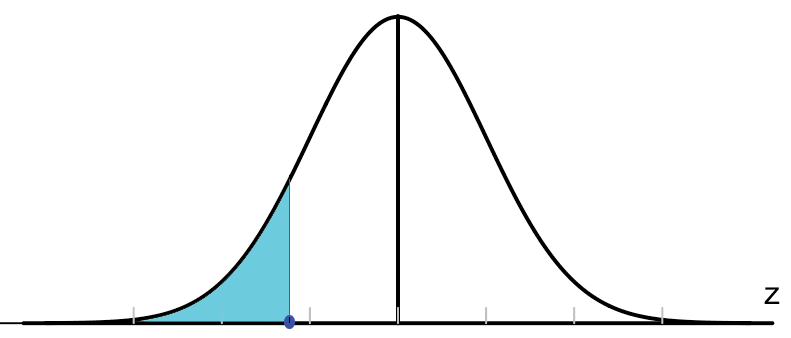

The following functions, only calculates the probability value (red line) when z is input.

z = -1.96;
p = normpdf(z)

p = 0.0584

The following function, calculates, the area value (indigo) when z value (blue) is input

P = normcdf(z)

P = 0.0250

The following function calculates the z value, when area value (in indigo) is input

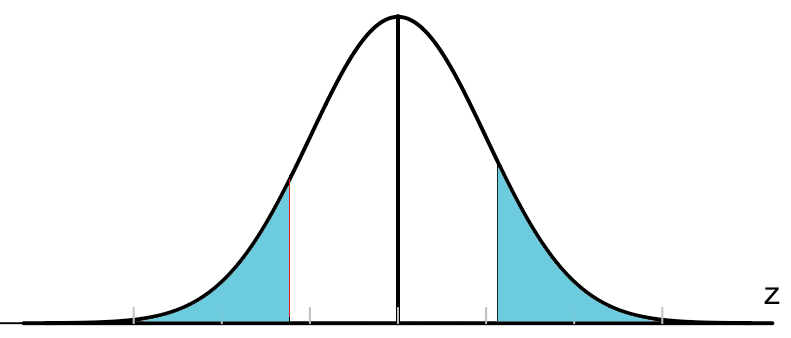

alf = 0.05;         % 1-LOC.; area value
P = alf/2;          % probab'
z_cr = norminv(P)   % critical z

z_cr = -1.9600

Now, let's see the following problem-

A1 = [28 17 36 35 32 33];
A2 = [12 31 19 14 20 19];

Diff = A2 - A1;
Dff_Ab = abs(Diff);

Now, le'ts assign rank to Diff_Ab

[srt, pos] = sort(Dff_Ab, 'ascend');     % sort Dff_Ab and find the ranks

[~, rnk] = sort(pos);                % put the ranks into position of Dff_Ab

Now, let's do the follows-

len = size(Diff,2);
    T_p = 0; T_n = 0; T_z = 0;          % initializer
    Diff_p = []; Diff_n = [];
    Diff_z = [];                        % initilizers
    rnk_p = []; rnk_n = []; rnk_z = [];
    kp = 1; kn = 1; kz = 1;
for i=1:1:len
    if Diff(i) > 0
        T_p = T_p + rnk(i);      % sums posv's rank
        Diff_p(kp) = Diff(i);    % tracks pos diff
        rnk_p(kp) = rnk(i);      % tracks ranks of psv's
        kp = kp +1;

    elseif Diff(i) < 0 
        T_n = T_n + rnk(i);      % sums ngv's rank
        Diff_n(kn) = Diff(i);    % tracks ngv diff
        rnk_n(kn) = rnk(i);      % tracks ranks of psv's
        kn = kn +1;

    else
        T_z = T_z + rnk(i);      % sums zeros rank
        Diff_z(kz) = Diff(i);
        rnk_z(kz) = rnk(i);      % tracks ranks of psv's
        kz = kz +1;
    end 
end 
T = [T_p, T_n];

Let's find the z-score now-

T = min(T)

T = 2

The following formula would be employed

n = length(Diff);        % sample size

    nm = T - n*(n+1)/4;
    dnm = sqrt( n*(n+1)*(2*n+1) /24);
z = nm /dnm

z = -1.7821

The null hypothesis would be rejeted if the observed z value falls within this area, where black dots shows $z_{\textrm{cr}}$

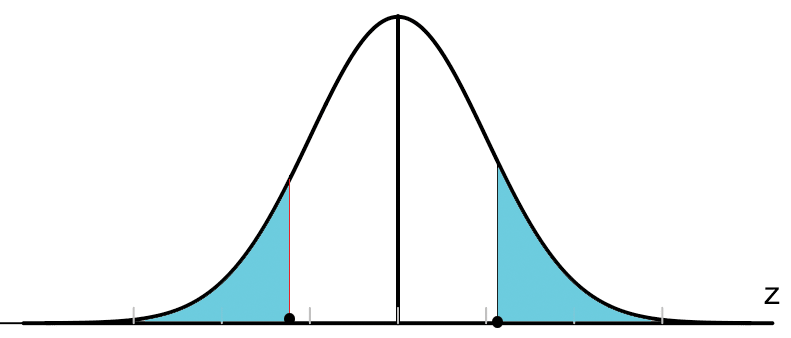 so,-

if abs(z) <= abs(z_cr)
    H = 'Accepted';
else
    H = 'Rejected';
end 
H

H = 'Accepted'

So, probability value, corresponding the found z-

P = normcdf(z)

P = 0.0374

So, when Null Hypothesis is accepted- it means- there's no signnificant difference in median value of prior and posterior findings/ results. So, that's not much change in the reading at two experiments.

A smaller p-value indicates a more significant difference between two data. It means, the data before, and data after are really different.

z = 0.253;
P = normcdf(z)

P = 0.5999

## Problem

Given

###############################

## Functions